# Linear Control Design II - Group Work Problem Module 2

## Description

In Figure 1 an electro-mechanical system is illustrated. The mechanical part is composed of a flexible structure buit by three masses interconnected by flexible beams. The electrical part is composed of a pair of EM_s. The lateral movements of the lower mass is coupled to the pair of EM_s by means of the EM_ic forces generated in the small gap illustrated in Figure 2. It means there is no mechanical contact between the two parts. The main goal is: a) to build an electro-mechanical model based on simplifying assumptions; b) to build a mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday; c) to build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t),\,\,x_2(t),\,\,x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$; d) investigate the vibrations of the structure when different initial conditions and inputs are present.

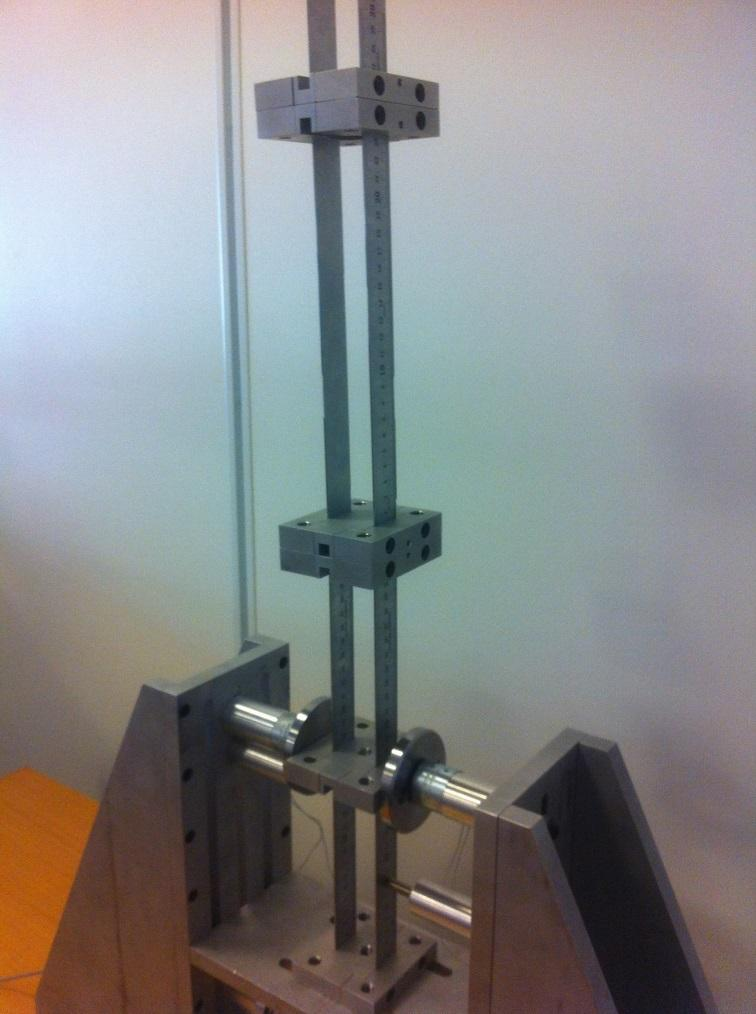


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


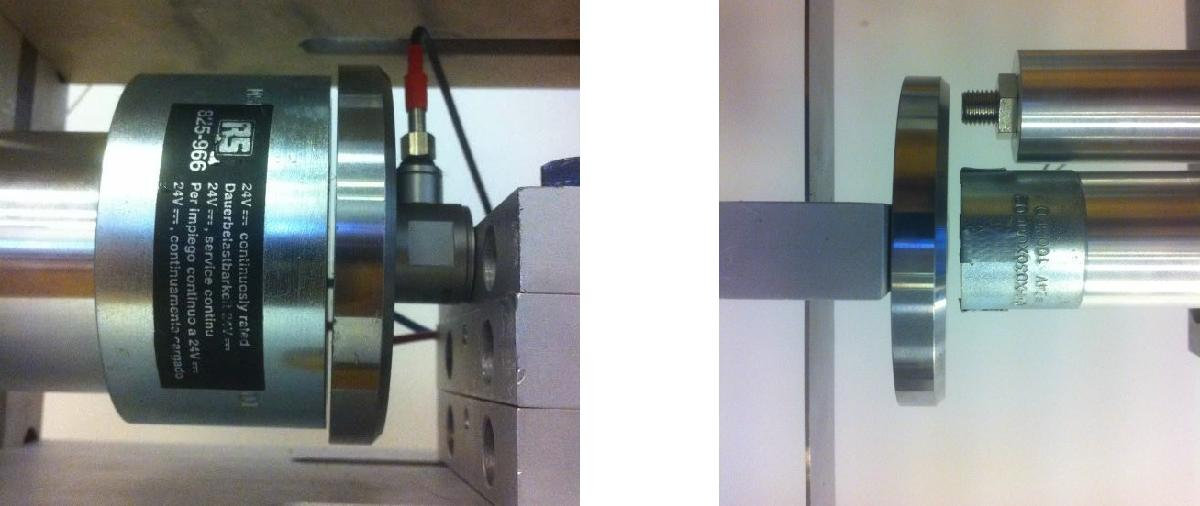


$$(a)\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad (b)$$



$$Figure\,2:\,The\,electro parts:\,(a)\,one\,single\,electromagnet\,and\,the\,gap\,where\,the\\ electromagnetic\,force\,will\,be\,generated\,by\,the\,input\,voltage\,u(t);\,(b)\,electromagnetic\\ actuator\,and\,eddy-current\,displacement\,sensor\,using\,to\,control\,and\,to\,measure\,the\\ lateral\,movements\,of\,the\,lower\,mass.$$


For the simulations the following parameters should be used.

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

R = 148.2;
L = 800e-3; % [H]

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

Ki5 = 22.4;
Ks5 = -313.6;

Ki3 = 37.33;
Ks3 = -871.11;

Ki2 = 56;
Ks2 = -1.96e3;

Ki1 = 112;
Ks1 = -7.84e3;

Where $Ki\#$ indicates the magnitude of the linearized force dependent on current change when the air gap $s_0$=$\#$ mm.

**Problem 1**

Build an electro-mechanical model based on simplifying assumptions.

% Your solution goes here:
% Derive by hand and/or upload picture


$$\begin{array}{l}
m_1 \ddot{x_1 } =-k_1 x_1 +k_2 \left(x_2 -x_1 \right)+f\left(t\right)\Rightarrow \ddot{x_1 } =-\frac{k_1 x_1 }{m_1 }+\frac{k_2 \left(x_2 -x_1 \right)}{m_1 }+\frac{f\left(t\right)}{m_1 }\\
m_2 \ddot{x_2 } =-k_2 \left(x_2 -x_1 \right)+k_3 \left(x_3 -x_2 \right)\Rightarrow \ddot{x_2 } =-\frac{k_2 \left(x_2 -x_1 \right)}{m_2 }+\frac{k_3 \left(x_3 -x_2 \right)}{m_2 }\\
m_3 \ddot{x_3 } =-k_3 \left(x_3 -x_2 \right)\Rightarrow \ddot{x_3 } =\frac{-k_3 \left(x_3 -x_2 \right)}{m_3 }\\
u\left(t\right)-v_r -v_l -v_c =0\Rightarrow u\left(t\right)-\mathit{Ri}-L\frac{\text{d}}{\text{d}t}i+K_i \dot{x_1 } =0\Rightarrow \dot{i} =-\frac{R}{L}i+\frac{K_i }{L}\dot{x_1 } +u\left(t\right)\\
f\left(t\right)=-\left(K_i i+K_s x_1 \right)
\end{array}$$


**Problem 2**

Build the mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday, based on the electro-mechanical model and simplifying assumptions done in problem 1.Use as main variables the  three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.

% Your solution goes here:
% Derive by hand and/or upload picture



$$\begin{array}{l}
\ddot{x_1 } =-\frac{\left(k_1 +k_2 +K_s \right)}{m_1 }x_1 +\frac{k_2 }{m_1 }x_2 -\frac{K_i i}{m_1 }\\
\ddot{x_2 } =\frac{k_2 }{m_2 }x_1 -\frac{k_2 +k_3 }{m_2 }x_2 +\frac{k_3 }{m_2 }x_3 \\
\ddot{x_3 } =\frac{k_3 }{m_3 }x_2 -\frac{k_3 }{m_3 }x_3 \\
\dot{i} =\frac{K_i }{L}\dot{x_1 } -\frac{R}{L}i+\frac{u\left(t\right)}{L}
\end{array}$$


**Problem 3**

Build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.  

% Your solution goes here:
% Fill in your code or upload picture


**Problem 4**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results.

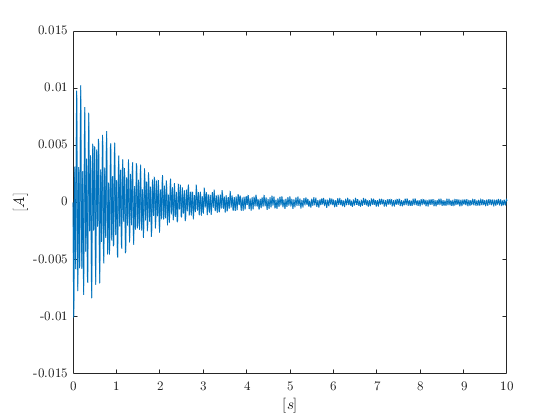

% Your solution goes here:
Ks = Ks5;
Ki = Ki5;
x0 = [0 0 1/1000 0 0 0 0];
u0 = 0;
sim('EM_Model')
figure
plot(i.time,i.signals.values),xlabel('$[s]$'),ylabel('$[A]$')

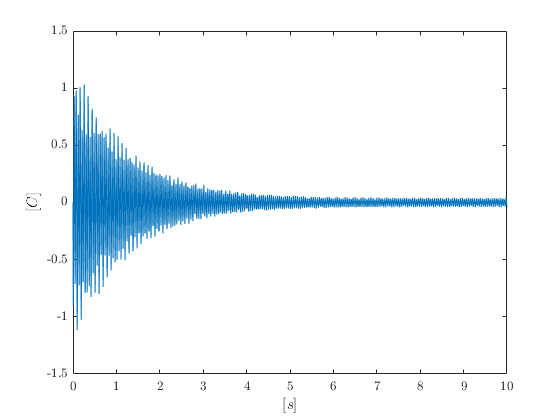

figure
plot(i_d.time,i_d.signals.values),xlabel('$[s]$'),ylabel('$[C]$')

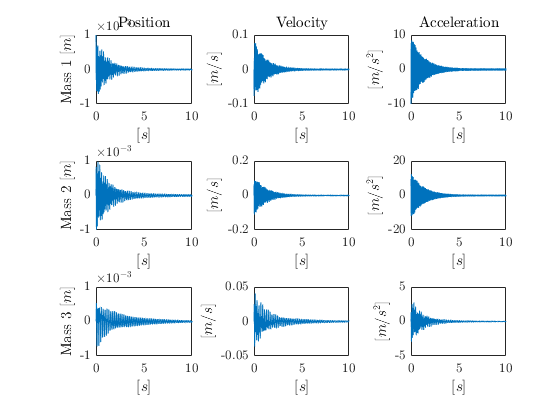

figure
subplot(3,3,1),plot(x1.time,x1.signals.values),xlabel('$[s]$'),ylabel('Mass 1 $[m]$'),title('Position')
subplot(3,3,4),plot(x2.time,x2.signals.values),xlabel('$[s]$'),ylabel('Mass 2 $[m]$')
subplot(3,3,7),plot(x3.time,x3.signals.values),xlabel('$[s]$'),ylabel('Mass 3 $[m]$')
subplot(3,3,2),plot(x1_d.time,x1_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$'),title('Velocity')
subplot(3,3,5),plot(x2_d.time,x2_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,8),plot(x3_d.time,x3_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,3),plot(x1_dd.time,x1_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$'),title('Acceleration')
subplot(3,3,6),plot(x2_dd.time,x2_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')
subplot(3,3,9),plot(x3_dd.time,x3_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')

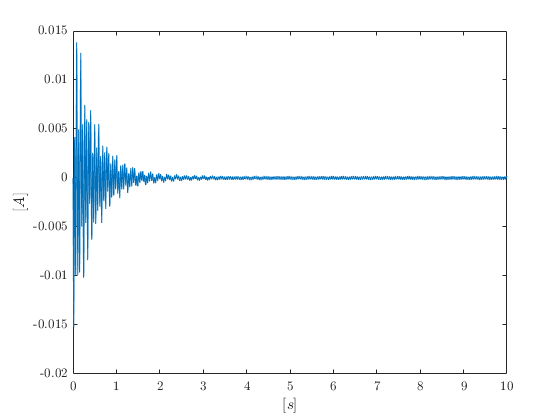

Ks = Ks3;
Ki = Ki3;
x0 = [0 0 1/1000 0 0 0 0];
u0 = 0;
sim('EM_Model')
figure
plot(i.time,i.signals.values),xlabel('$[s]$'),ylabel('$[A]$')

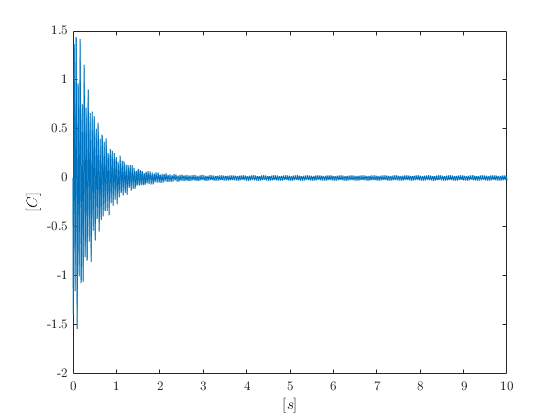

figure
plot(i_d.time,i_d.signals.values),xlabel('$[s]$'),ylabel('$[C]$')

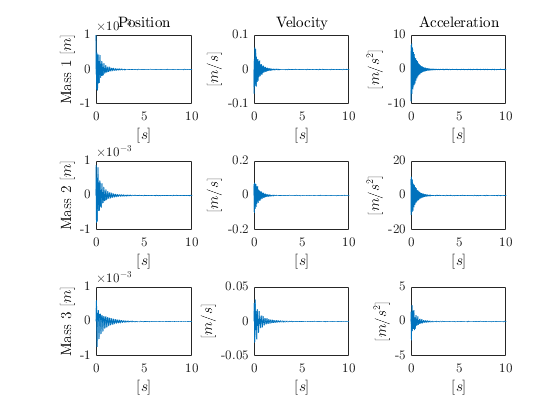

figure
subplot(3,3,1),plot(x1.time,x1.signals.values),xlabel('$[s]$'),ylabel('Mass 1 $[m]$'),title('Position')
subplot(3,3,4),plot(x2.time,x2.signals.values),xlabel('$[s]$'),ylabel('Mass 2 $[m]$')
subplot(3,3,7),plot(x3.time,x3.signals.values),xlabel('$[s]$'),ylabel('Mass 3 $[m]$')
subplot(3,3,2),plot(x1_d.time,x1_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$'),title('Velocity')
subplot(3,3,5),plot(x2_d.time,x2_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,8),plot(x3_d.time,x3_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,3),plot(x1_dd.time,x1_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$'),title('Acceleration')
subplot(3,3,6),plot(x2_dd.time,x2_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')
subplot(3,3,9),plot(x3_dd.time,x3_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')

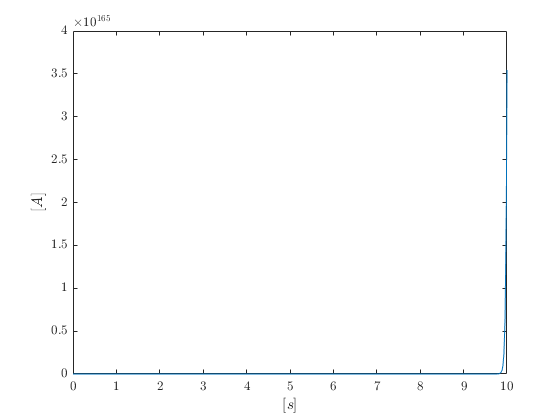

Ks = Ks1;
Ki = Ki1;
x0 = [0 0 1/1000 0 0 0 0];
u0 = 0;
sim('EM_Model')
figure
plot(i.time,i.signals.values),xlabel('$[s]$'),ylabel('$[A]$')

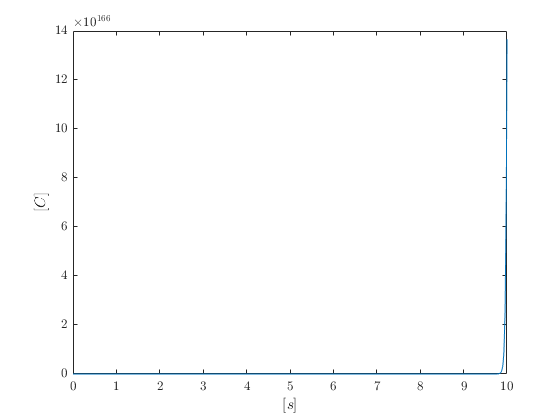

figure
plot(i_d.time,i_d.signals.values),xlabel('$[s]$'),ylabel('$[C]$')

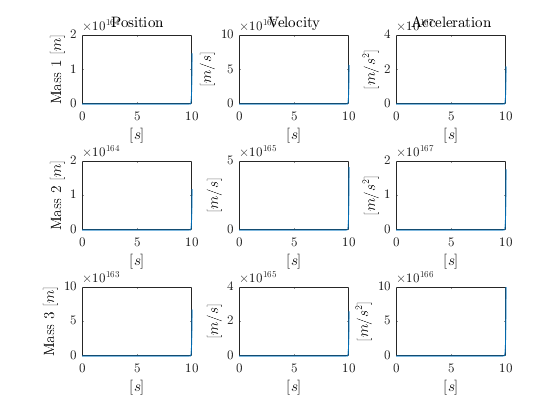

figure
subplot(3,3,1),plot(x1.time,x1.signals.values),xlabel('$[s]$'),ylabel('Mass 1 $[m]$'),title('Position')
subplot(3,3,4),plot(x2.time,x2.signals.values),xlabel('$[s]$'),ylabel('Mass 2 $[m]$')
subplot(3,3,7),plot(x3.time,x3.signals.values),xlabel('$[s]$'),ylabel('Mass 3 $[m]$')
subplot(3,3,2),plot(x1_d.time,x1_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$'),title('Velocity')
subplot(3,3,5),plot(x2_d.time,x2_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,8),plot(x3_d.time,x3_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,3),plot(x1_dd.time,x1_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$'),title('Acceleration')
subplot(3,3,6),plot(x2_dd.time,x2_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')
subplot(3,3,9),plot(x3_dd.time,x3_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')

**Problem 5**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

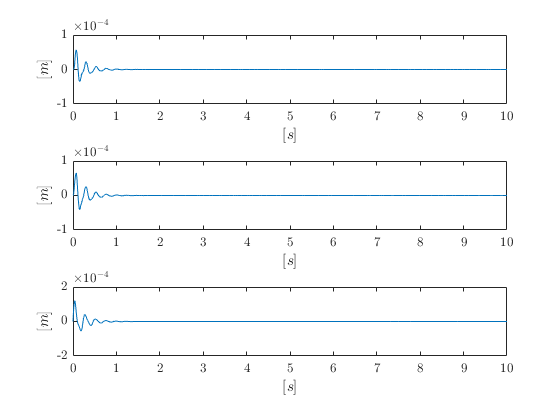

% Your solution goes here:
x0 = [0 0 0 0 0 5/1000 0];
u0 = 0;
Ks=Ks2;
Ki=Ki2;
sim('EM_Model')
figure
subplot(3,1,1),plot(x1.time,x1.signals.values),ylabel('$[m]$'),xlabel('$[s]$')
subplot(3,1,2),plot(x2.time,x2.signals.values),ylabel('$[m]$'),xlabel('$[s]$')
subplot(3,1,3),plot(x3.time,x3.signals.values),ylabel('$[m]$'),xlabel('$[s]$')

**Problem 6**

A step function $u(t)$=10 V is send to the EM_s, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies.

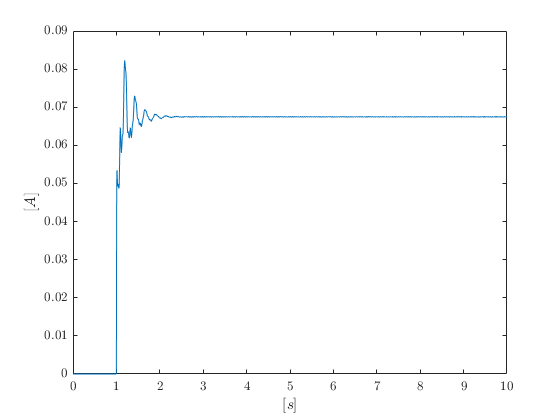

% Your solution goes here:
x0 = [0 0 0 0 0 0 0];
u0 = 10;
sim('EM_Model')
figure
plot(i.time,i.signals.values),xlabel('$[s]$'),ylabel('$[A]$')

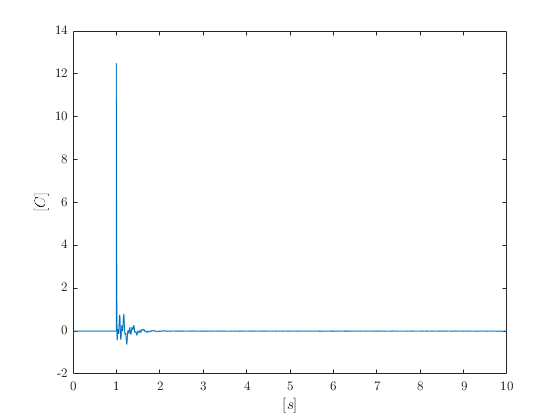

figure
plot(i_d.time,i_d.signals.values),xlabel('$[s]$'),ylabel('$[C]$')

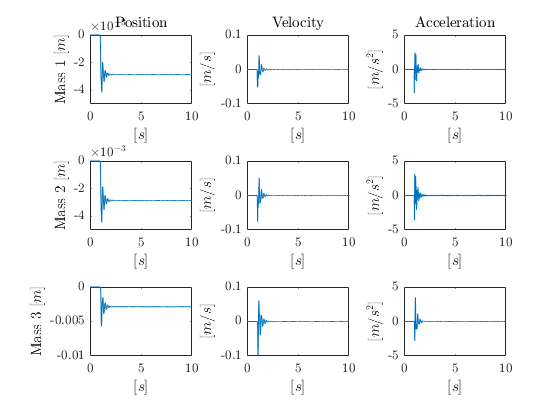

figure
subplot(3,3,1),plot(x1.time,x1.signals.values),xlabel('$[s]$'),ylabel('Mass 1 $[m]$'),title('Position')
subplot(3,3,4),plot(x2.time,x2.signals.values),xlabel('$[s]$'),ylabel('Mass 2 $[m]$')
subplot(3,3,7),plot(x3.time,x3.signals.values),xlabel('$[s]$'),ylabel('Mass 3 $[m]$')
subplot(3,3,2),plot(x1_d.time,x1_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$'),title('Velocity')
subplot(3,3,5),plot(x2_d.time,x2_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,8),plot(x3_d.time,x3_d.signals.values),xlabel('$[s]$'),ylabel('$[m/s]$')
subplot(3,3,3),plot(x1_dd.time,x1_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$'),title('Acceleration')
subplot(3,3,6),plot(x2_dd.time,x2_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')
subplot(3,3,9),plot(x3_dd.time,x3_dd.signals.values),xlabel('$[s]$'),ylabel('$[m/s^2]$')